Data Science (Prof. Neff)                Versuchsdatum 28.10.2020

Bestimmung der Viskosität von Spülmittel

Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),

                    Anna Kuhn (2051063), Michael Schulze (2061282)

Rohdaten der einzelnen Gruppenmitglieder

dataMichael = readtable("Blasen_Steigzeit_Michael.csv");
%imageFrosch = imread("frosch_AleoVera_Spuellotion.png");
dataBenjamin = readtable("Blasen_Steigzeit_Benjamin.csv");
%imageW5 = imread("W5_eco.png");
dataJan = readtable("Blasen_Steigzeit_Jan.csv");
dataAnna = readtable("Blasen_Steigzeit_Anna.csv");
%imageEcover = imread("ecover_Colorwaschmittel.png");

%Michael
disp(" ")

disp(" I) --- Messwerte Michael - Frosch Aloe Vera Spül-Lotion ---")

 I) --- Messwerte Michael - Frosch Aloe Vera Spül-Lotion ---


data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

      2              19              
    3.5             9.8              
    3.5             9.7              
      3             8.8              
      2            21.5              
      4               8              
      4             8.8              
      3             9.7              
    2.5              22              
      3            11.5              


 
 1a) Viskosität über den Mittelwert aus 10 Messungen 


mittelwert = 1.2035

standardabweichung = 0.2735

standardunsicherheit = 0.0865

 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 


T = 10×6 table
      d           v          eta      deltaEta     reynold     turbulent
    ______    _________    _______    ________    _________    _________

     0.002    0.0026316    0.84911     1.1125     0.0063534    false    
    0.0035     0.005102     1.3413    0.99237      0.013647    false    
    0.0035    0.0051546     1.3276    0.98119      0.013929    false    
     0.003    0.0056818    0.88486    0.74724      0.019745    false    
     0.002    0.0023256    0.96083      1.281     0.0049618    false    
     0.004      0.00625     1.4301    0.91949      0.017919    false    
     0.004    0.0056818     1.5731     1.0213      0.014809    false    
     0.003    0.0051546    0.97536    0.82941      0.016251    false    
    0.0025    0.0022727     1.5362     1.7178     

 
 2) Viskosität über lineare Regression 


ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    ________    _________

    (Intercept)    -3.7679e-07    5.8891e-07    -0.63982      0.54018
    x1              0.00063237    0.00012578      5.0275    0.0010174


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 5.66e-07
R-squared: 0.76,  Adjusted R-Squared 0.73
F-statistic vs. constant model: 25.3, p-value = 0.00102

 
 Übersicht der berechneten Viskositäten 


p = 68.7200

t = 1.0600

 
 1a) Viskosität über den Mittelwert aus 10 Messungen 
η = 1.2035 ± 0.0917 bzw. als Intervall [1.1118 ... 1.2952] Ns/m²
 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 
η = 0.8491 ± 1.1792 bzw. als Intervall [-0.3301 ... 2.0284] Ns/m²
η = 1.3413 ± 1.0519 bzw. als Intervall [0.2893 ... 2.3932] Ns/m²
η = 1.3276 ± 1.0401 bzw. als Intervall [0.2875 ... 2.3676] Ns/m²
η = 0.8849 ± 0.7921 bzw. als Intervall [0.0928 ... 1.6769] Ns/m²
η = 0.9608 ± 1.3578 bzw. als Intervall [-0.3970 ... 2.3187] Ns/m²
η = 1.4301 ± 0.9747 bzw. als Intervall [0.4554 ... 2.4047] Ns/m²
η = 1.5731 ± 1.0825 bzw. als Intervall [0.4906 ... 2.6556] Ns/m²
η = 0.9754 ± 0.8792 bzw. als Intervall [0.0962 ... 1.8545] Ns/m²
η = 1.5362 ± 1.8209 bzw. als Intervall [-0.2847 ... 3.3571] Ns/m²
η = 1.1564 ± 1.0587 bzw. als Intervall [0.0977 ... 2.2150] Ns/m²
 
 2) Viskosität über lineare Regression 
η = 1.4130 ± 1.4978 bzw. als Intervall [-0.0848 ... 2.9108]

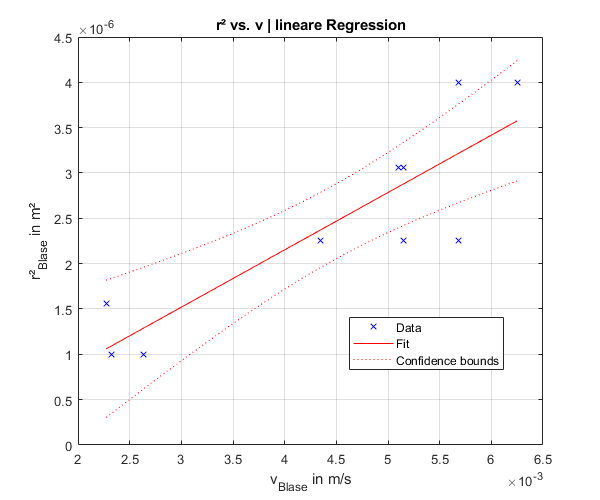

%imshow(imageFrosch)
[d1, v1, a1, b1] = eval_data(dataMichael);

%Benjamin
disp(" ")

disp(" II) --- Messwerte Benjamin - W5 eco ---")

 II) --- Messwerte Benjamin - W5 eco ---


data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

      2             54               
      3             26               
      4             16               
      4             13               
    0.5            287               
    1.5             44               
    0.3            570               
      4             11               
      1             64               
      1             83               


 
 1a) Viskosität über den Mittelwert aus 10 Messungen 


mittelwert = 1.6301

standardabweichung = 0.8881

standardunsicherheit = 0.2809

 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 


T = 10×6 table
      d           v           eta      deltaEta     reynold      turbulent
    ______    __________    _______    ________    __________    _________

     0.002    0.00092593     2.4133    4.3503      0.00078655    false    
     0.003     0.0019231     2.6144    2.7072       0.0022619    false    
     0.004      0.003125     2.8602    2.0795       0.0044796    false    
     0.004     0.0038462     2.3239     1.604       0.0067857    false    
    0.0005    0.00017422    0.80163    6.8688      0.00011138    false    
    0.0015     0.0011364     1.1061    2.1641       0.0015796    false    
    0.0003    8.7719e-05    0.57315    9.2703      4.7062e-05    false    
     0.004     0.0045455     1.9664    1.3156       0.0094776    false    
     0.001    0.00078125    0.

 
 2) Viskosität über lineare Regression 


ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)    -1.9038e-07    2.2687e-07    -0.83917       0.42574
    x1               0.0010673    9.9415e-05      10.736    4.9843e-06


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 4.73e-07
R-squared: 0.935,  Adjusted R-Squared 0.927
F-statistic vs. constant model: 115, p-value = 4.98e-06

 
 Übersicht der berechneten Viskositäten 


p = 68.7200

t = 1.0600

 
 1a) Viskosität über den Mittelwert aus 10 Messungen 
η = 1.6301 ± 0.2977 bzw. als Intervall [1.3324 ... 1.9278] Ns/m²
 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 
η = 2.4133 ± 4.6113 bzw. als Intervall [-2.1981 ... 7.0246] Ns/m²
η = 2.6144 ± 2.8696 bzw. als Intervall [-0.2552 ... 5.4840] Ns/m²
η = 2.8602 ± 2.2042 bzw. als Intervall [0.6559 ... 5.0644] Ns/m²
η = 2.3239 ± 1.7002 bzw. als Intervall [0.6237 ... 4.0241] Ns/m²
η = 0.8016 ± 7.2810 bzw. als Intervall [-6.4793 ... 8.0826] Ns/m²
η = 1.1061 ± 2.2940 bzw. als Intervall [-1.1879 ... 3.4001] Ns/m²
η = 0.5731 ± 9.8265 bzw. als Intervall [-9.2533 ... 10.3996] Ns/m²
η = 1.9664 ± 1.3945 bzw. als Intervall [0.5719 ... 3.3608] Ns/m²
η = 0.7150 ± 2.2042 bzw. als Intervall [-1.4892 ... 2.9193] Ns/m²
η = 0.9273 ± 3.1290 bzw. als Intervall [-2.2017 ... 4.0564] Ns/m²
 
 2) Viskosität über lineare Regression 
η = 2.3848 ± 2.5279 bzw. als Intervall [-0.1431 ... 4.

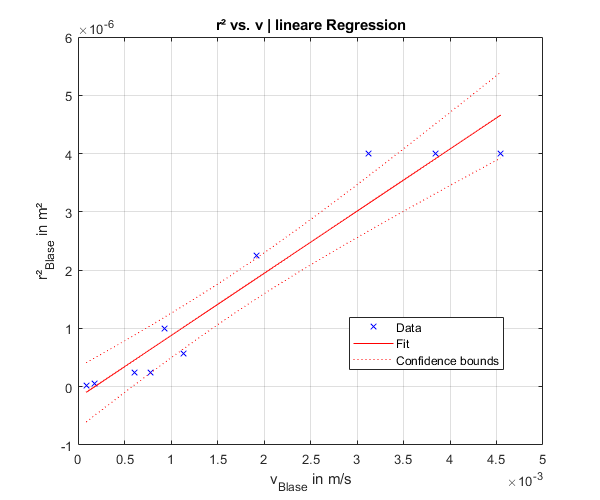

%imshow(imageW5)
[d2, v2, a2, b2] = eval_data(dataBenjamin);

%Jan
disp(" ")

disp(" III) --- Messwerte Jan - Frosch Aloe Vera Spül-Lotion ---")

 III) --- Messwerte Jan - Frosch Aloe Vera Spül-Lotion ---


data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

    4                10              
    2              16.7              
    2                50              
    5               1.9              
    3              12.5              
    3              16.7              
    2              16.7              
    2                25              
    5               2.5              
    5                 5              


 
 1a) Viskosität über den Mittelwert aus 10 Messungen 


mittelwert = 1.2194

standardabweichung = 0.5579

standardunsicherheit = 0.1764

 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 


T = 10×6 table
      d         v          eta      deltaEta     reynold      turbulent
    _____    ________    _______    ________    __________    _________

    0.004       0.005     1.7876      1.179       0.011468    false    
    0.002    0.002994    0.74632    0.96369       0.008224    false    
    0.002       0.001     2.2345     3.8703     0.00091743    false    
    0.005    0.026316    0.53069    0.26116        0.25414    true     
    0.003       0.004     1.2569      1.096      0.0097859    false    
    0.003    0.002994     1.6792     1.5335      0.0054826    false    
    0.002    0.002994    0.74632    0.96369       0.008224    false    
    0.002       0.002     1.1172     1.5299      0.0036697    false    
    0.005        0.02    0.69828    0.34475        0.14679  

 
 2) Viskosität über lineare Regression 


ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat      pValue  
                   __________    __________    ______    _________

    (Intercept)    1.3295e-06    5.6794e-07     2.341     0.047341
    x1             0.00023228    5.0487e-05    4.6007    0.0017538


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 1.3e-06
R-squared: 0.726,  Adjusted R-Squared 0.691
F-statistic vs. constant model: 21.2, p-value = 0.00175

 
 Übersicht der berechneten Viskositäten 


p = 68.7200

t = 1.0600

 
 1a) Viskosität über den Mittelwert aus 10 Messungen 
η = 1.2194 ± 0.1870 bzw. als Intervall [1.0324 ... 1.4064] Ns/m²
 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 
η = 1.7876 ± 1.2497 bzw. als Intervall [0.5379 ... 3.0373] Ns/m²
η = 0.7463 ± 1.0215 bzw. als Intervall [-0.2752 ... 1.7678] Ns/m²
η = 2.2345 ± 4.1025 bzw. als Intervall [-1.8680 ... 6.3370] Ns/m²
η = 0.5307 ± 0.2768 bzw. als Intervall [0.2539 ... 0.8075] Ns/m²
η = 1.2569 ± 1.1618 bzw. als Intervall [0.0951 ... 2.4187] Ns/m²
η = 1.6792 ± 1.6255 bzw. als Intervall [0.0537 ... 3.3048] Ns/m²
η = 0.7463 ± 1.0215 bzw. als Intervall [-0.2752 ... 1.7678] Ns/m²
η = 1.1172 ± 1.6216 bzw. als Intervall [-0.5044 ... 2.7389] Ns/m²
η = 0.6983 ± 0.3654 bzw. als Intervall [0.3328 ... 1.0637] Ns/m²
η = 1.3966 ± 0.7475 bzw. als Intervall [0.6490 ... 2.1441] Ns/m²
 
 2) Viskosität über lineare Regression 
η = 0.5190 ± 0.5502 bzw. als Intervall [-0.0311 ... 1.0692

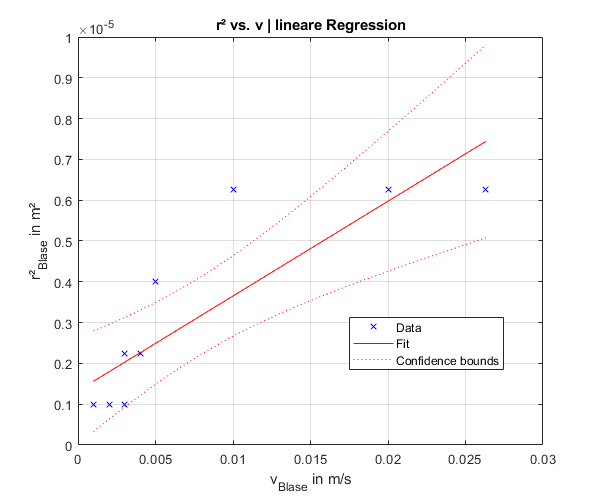

%imshow(imageFrosch)
[d3, v3, a3, b3] = eval_data(dataJan);

%Anna
disp(" ")

disp(" IV) --- Messwerte Anna - ecover Colorwaschmittel flüssig Konzentrat Apfelblüte & Freesie ---")

 IV) --- Messwerte Anna - ecover Colorwaschmittel flüssig Konzentrat Apfelblüte & Freesie ---


data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

    1.5            15.2              
      1              25              
      3            13.2              
      2            13.9              
      1              20              
    0.5            33.3              
      3            13.1              
      3            13.9              
      5               1              
    4.5               2              


 
 1a) Viskosität über den Mittelwert aus 10 Messungen 


mittelwert = 0.6373

standardabweichung = 0.5099

standardunsicherheit = 0.1612

 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 


T = 10×6 table
      d           v          eta       deltaEta     reynold     turbulent
    ______    _________    ________    ________    _________    _________

    0.0015    0.0032895      0.3821    0.63998      0.013236    false    
     0.001        0.002     0.27931    0.70523     0.0073394    false    
     0.003    0.0037879      1.3273     1.1656     0.0087756    false    
     0.002    0.0035971     0.62119    0.78965      0.011871    false    
     0.001       0.0025     0.22345    0.55818      0.011468    false    
    0.0005    0.0015015    0.093011    0.46193     0.0082734    false    
     0.003    0.0038168      1.3172     1.1556       0.00891    false    
     0.003    0.0035971      1.3977     1.2364     0.0079139    false    
     0.005         0.05     0.27931    0

 
 2) Viskosität über lineare Regression 


ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat       pValue  
                   __________    _________    ______    __________

    (Intercept)    8.1028e-07    3.685e-07    2.1989      0.059097
    x1             0.00012196    2.059e-05    5.9232    0.00035241


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 9.7e-07
R-squared: 0.814,  Adjusted R-Squared 0.791
F-statistic vs. constant model: 35.1, p-value = 0.000352

 
 Übersicht der berechneten Viskositäten 


p = 68.7200

t = 1.0600

 
 1a) Viskosität über den Mittelwert aus 10 Messungen 
η = 0.6373 ± 0.1709 bzw. als Intervall [0.4664 ... 0.8082] Ns/m²
 
 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit 
η = 0.3821 ± 0.6784 bzw. als Intervall [-0.2963 ... 1.0605] Ns/m²
η = 0.2793 ± 0.7475 bzw. als Intervall [-0.4682 ... 1.0269] Ns/m²
η = 1.3273 ± 1.2355 bzw. als Intervall [0.0917 ... 2.5628] Ns/m²
η = 0.6212 ± 0.8370 bzw. als Intervall [-0.2158 ... 1.4582] Ns/m²
η = 0.2235 ± 0.5917 bzw. als Intervall [-0.3682 ... 0.8151] Ns/m²
η = 0.0930 ± 0.4896 bzw. als Intervall [-0.3966 ... 0.5827] Ns/m²
η = 1.3172 ± 1.2249 bzw. als Intervall [0.0923 ... 2.5422] Ns/m²
η = 1.3977 ± 1.3106 bzw. als Intervall [0.0870 ... 2.7083] Ns/m²
η = 0.2793 ± 0.1452 bzw. als Intervall [0.1341 ... 0.4245] Ns/m²
η = 0.4525 ± 0.2621 bzw. als Intervall [0.1904 ... 0.7146] Ns/m²
 
 2) Viskosität über lineare Regression 
η = 0.2725 ± 0.2889 bzw. als Intervall [-0.0164 ... 0.561

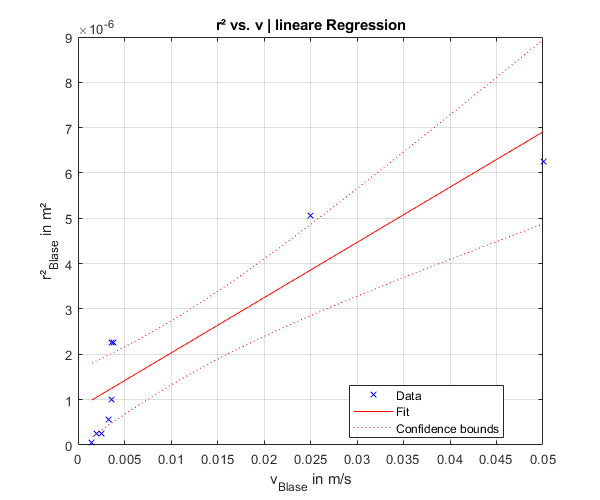

%imshow(imageEcover)
[d4, v4, a4, b4] = eval_data(dataAnna);

Plot aller Werte

disp(" ")

disp(" Plotten der Einzelwerte und Ausgleichsgeraden aller Gruppenmitglieder ")

 Plotten der Einzelwerte und Ausgleichsgeraden aller Gruppenmitglieder 


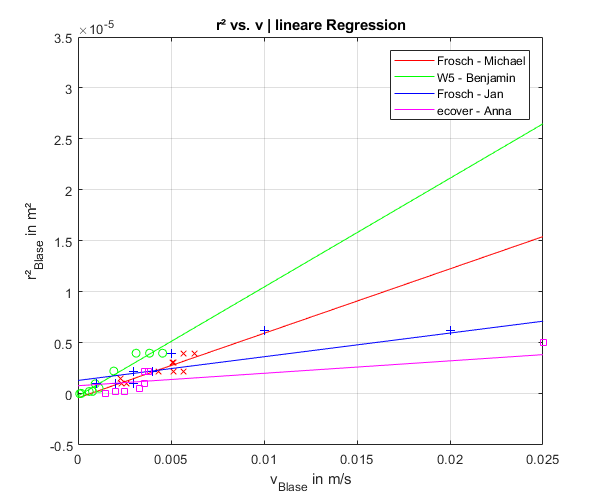

x = (0:1e-3:50*1e-3);

y1 = a1*x + b1;
y2 = a2*x + b2;
y3 = a3*x + b3;
y4 = a4*x + b4;

h1 = plot(x,y1, "r");
hold on;
    plot(v1,(d1 ./2).^2, "rx");

    h2 = plot(x,y2, "g");
    plot(v2,(d2 ./2).^2, "go");

    h3 = plot(x,y3, "b");
    plot(v3,(d3 ./2).^2, "b+");
    
    h4 = plot(x,y4, "m");
    plot(v4,(d4 ./2).^2, "ms");
    
    grid on;
    title('r² vs. v | lineare Regression');
    ylabel('r²_{Blase} in m²', 'Interpreter', 'tex');
    xlabel('v_{Blase} in m/s', 'Interpreter', 'tex');
    legend([h1 h2 h3 h4], {"Frosch - Michael","W5 - Benjamin", "Frosch - Jan","ecover - Anna"});
    set(gcf, 'position', [0.0000, -0.0000050, 600, 500])
    xlim([0.0000 0.025]);
    ylim([-0.0000050 0.0000350]);
hold off;


disp(" ")

disp("Wie im Bericht beschrieben können wir die lineare Regression nur für die Messdaten von Michael und Benjamin anwenden.")

Wie im Bericht beschrieben können wir die lineare Regression nur für die Messdaten von Michael und Benjamin anwenden.


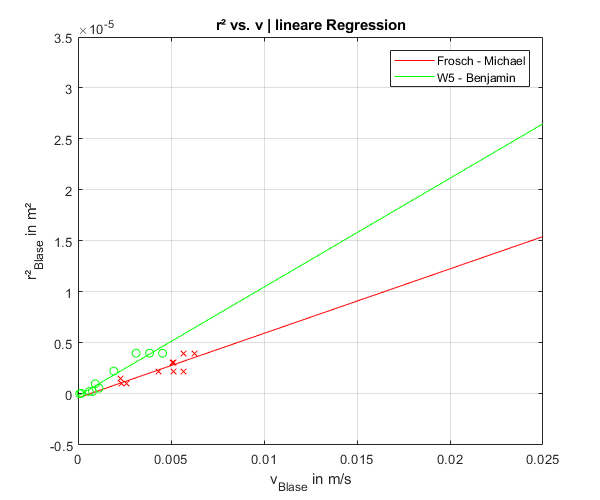


h1 = plot(x,y1, "r");
hold on;
    plot(v1,(d1 ./2).^2, "rx");

    h2 = plot(x,y2, "g");
    plot(v2,(d2 ./2).^2, "go");
    
    grid on;
    title('r² vs. v | lineare Regression');
    ylabel('r²_{Blase} in m²', 'Interpreter', 'tex');
    xlabel('v_{Blase} in m/s', 'Interpreter', 'tex');
    legend([h1 h2], {"Frosch - Michael","W5 - Benjamin"});
    set(gcf, 'position', [0.0000, -0.0000050, 600, 500])
    xlim([0.0000 0.025]);
    ylim([-0.0000050 0.0000350]);
hold off;

function [r_d, r_v, r_a, r_b] = eval_data(tmpdata)
    % Rückgabewerte sind Durchmesser d und Geschwindigkeit v
    % sowie Koeffizienten der Geradengleichung y = a*x + b
    data = tmpdata

            Konstanten

    s = 0.05;                    %Blasen wurden über einen Weg von 5 cm betrachtet
    g = 9.81;                    %m/s²
    %Vergleichswert Sicherheitsdatenblatt Frosch Aleo Vera Spül-Lotion
    etaDatenblatt = 1.500;       

            Steigzeit der Blasen für 5 cm in s

    t = data.Steigzeit_5cm_in_s;

            Geschwindigkeit der Blasen in m/s

    v = s ./ t;

            Durchmesser der Blasen in m

    d = data.Blase_in_mm .* 1e-3;
    
    r = d / 2;

            Dichte des Spülmittels in kg/m³

    %aus Sicherheitsdatenblatt Frosch Aleo Vera Spül-Lotion
    rho = 1025;

            Viskosität des Spülmittels in N*s/m²

    eta = (2*rho*g * (d ./2).^2) ./ (9 .* v);

            Statistische Kenngrößen der berechneten Viskosität

    disp(" ")
    disp(" 1a) Viskosität über den Mittelwert aus 10 Messungen ")
    mittelwert = mean(eta)
    standardabweichung = std(eta)
    standardunsicherheit = standardabweichung / sqrt(length(eta))

            Reynolds-Zahl zur Abschätzung der Strömung

    reynold = (v .* d .* rho) ./ (eta);
    %Kugeln ab Re > 0.2 als turbulente Strömung
    turbulent = reynold > 0.2;

            Abschätzung der Unsicherheiten

    disp(" ")
    disp(" 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit ")
    %geschätzte Unsicherheit für Durchmesser 
    % 0.5 mm (Halber Milimeter nach Augenmaß abschätzbar)
    b_deltaD = 0.5 * 1e-3;
    %geschätzte Unsicherheit für Zeit 0.5 s 
    % (Genaugigkeit von 0.5 Sekunden durch Software bestimmbar)
    b_deltaT = 0.5;
    %geschätzte Unsicherheit für Geschwindigkeit m/s
    b_deltaV = b_deltaD / b_deltaT;
    
    %Dreieckverteilung Geschwindigkeit
    u_Vdreieck = b_deltaV / 2 * sqrt(6);
    %Dreieckverteilung Durchmesser
    u_Ddreieck = b_deltaD / 2 * sqrt(6);

            Fehlerfortpflanzung - Kombinierte Standardunsicherheit

    %Ableitung eta nach Geschwindigkeit
    dEta_dV = - (2 * r.^2 * g * rho) ./ (9 * v.^2);
    %Ableitung eta nach Radius
    dEta_dR = (4 * g * rho * r) ./ (9 * v);
    
    %Kombinierte Standardunsicherheit
    deltaEta = sqrt((dEta_dV .* u_Vdreieck).^2 + (dEta_dR .* u_Ddreieck).^2);

            Darstellung der Werte als Tabelle

    %varNames = {"d in m" "v in m/s" "eta in Ns/m²" "delta eta" "Re" "Turbulent?"}
    T = table(d, v, eta, deltaEta, reynold, turbulent)

            Ausgleichsgerade (lineare Regression) von r² zu v

    disp(" ")
    disp(" 2) Viskosität über lineare Regression ")
    ausgleichsgerade = fitlm(v,(d ./2).^2, "linear")
    steigung = ausgleichsgerade.Coefficients.Estimate(2);
    intercept = ausgleichsgerade.Coefficients.Estimate(1);
    se_v = ausgleichsgerade.Coefficients.SE(2);
    se_r_2 = ausgleichsgerade.Coefficients.SE(1);

            Plotten der Werte und Ausgleichsgeraden

    %plot(v,(d ./2).^2, "x")
    %hold on
        plot(ausgleichsgerade)
        grid on
        title('r² vs. v | lineare Regression')
        ylabel('r²_{Blase} in m²', 'Interpreter', 'tex')
        xlabel('v_{Blase} in m/s', 'Interpreter', 'tex')
        set(gcf, 'position', [0.0000, -0.0000050, 600, 500])
    %hold off

            Rückgabewerte

    r_d = d;
    r_v = v;
    r_a = steigung;
    r_b = intercept;
    
    %r.^2 = (9 * eta * v) / (2 * g * rho)
    
    %Zufallspunkt
    v = 0.5;
    
    %Ausgleichsgerade Y-Wert zu Zufallspunkt
    r_2 = v * r_a;
    
    eta_linReg = (r_2 * 2 * g * rho) / (9 * v);
    
    
    %Ableitung eta nach Steigung
    dEta_dm = (2 * g * rho) / 9;
    %Ableitung eta nach Radius
    %dEta_dR = (4 * g * rho * sqrt(r_2)) / (9 * v)
    
    %Kombinierte Standardunsicherheit Lineare Regression
    deltaEta_LinReg = abs(dEta_dm * se_r_2);

    disp(" ")
    disp(" Übersicht der berechneten Viskositäten ")   
    
    %% t-Verteilung für wenige Messwerte
    % Freiheitsgrade v = 9 %v = n - 1
    p = 68.72 %Aus Tabelle (GUM Arbeiten mit Messdaten S. 94)
    t = 1.06 %Aus Tabelle (GUM Arbeiten mit Messdaten S. 94)
    
    disp(" ")
    disp(" 1a) Viskosität über den Mittelwert aus 10 Messungen ")
    Eta_Intervall1 = [mittelwert - t * standardunsicherheit, mittelwert + t * standardunsicherheit];
    text = sprintf("%s = %0.4f %s %0.4f bzw. als Intervall [%0.4f ... %0.4f] Ns/m²",char(951), mittelwert, char(177), t * standardunsicherheit, mittelwert - t * standardunsicherheit, mittelwert + t * standardunsicherheit);
    disp(text)
    
    disp(" ")
    disp(" 1b) Viskosität über Einzelwerte mit kombinierter Standardunsicherheit ")
    Eta_Intervall2 = [eta, -t*deltaEta,eta,t*deltaEta];
    for i = 1:length(eta)
        text = sprintf("%s = %0.4f %s %0.4f bzw. als Intervall [%0.4f ... %0.4f] Ns/m²",char(951), eta(i,1), char(177), t * deltaEta(i,1), eta(i,1) - t * deltaEta(i,1), eta(i,1) + t * deltaEta(i,1));
        disp(text)    
    end
    
    disp(" ")
    disp(" 2) Viskosität über lineare Regression ")
    Eta_Intervall3 = [eta_linReg - t * deltaEta_LinReg, eta_linReg + t * deltaEta_LinReg];
    text = sprintf("%s = %0.4f %s %0.4f bzw. als Intervall [%0.4f ... %0.4f] Ns/m²",char(951), eta_linReg, char(177), t * eta_linReg, eta_linReg - t * eta_linReg, eta_linReg + t * eta_linReg);
    disp(text)
    
end